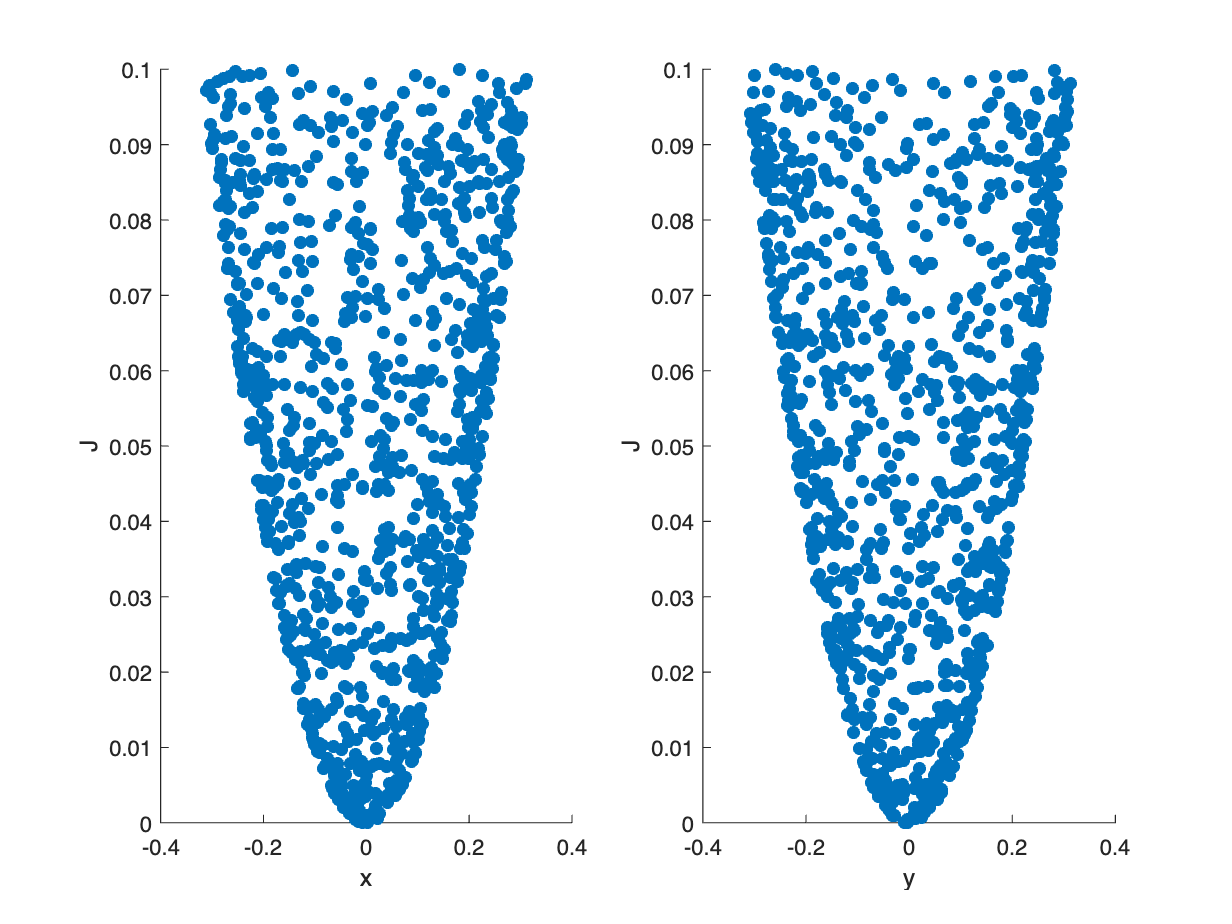


f = @(x) x(1)^2 + x(2)^2;

out = zeros(1000,3);
i = 1;
while i <= 1000
    x = -2 + 4*rand;
    y = -2 + 4*rand;
    
    J =  f([x,y]);
    if J <= 0.1
        out(i,1) = f([x,y]);
        out(i,2) = x;
        out(i,3) = y;
        i = i + 1;
    end 
    
end 

subplot(1,2,1)
scatter(out(:,2),out(:,1),'filled')
xlabel('x');
ylabel('J');

subplot(1,2,2)
scatter(out(:,3),out(:,1),'filled')
xlabel('y');
ylabel('J'); 

% options = optimset('PlotFcns','optimplotfval','TolFun',1e-7,'TolX', 1e-7,'MaxIter', 1200);

% [bp,fval] = fminsearch(f,[2 2])  %, options);
% [bp11,fval11] = fminsearch(f,[1000 1000])
% 
% disp(bp(1))

% % options = optimset('PlotFcns','optimplotfval','TolFun',1e-7,'TolX', 1e-7, 'MaxIter', 1600);
% 
% 
% ff = @(x) f([x 2]);
% 
% [bp2,fval2] = fminsearch(ff,2)  %, options);
% [bp3,fval3] = fminsearch(ff,4) 
% 
% [bp4,fval4] = fminsearch(ff,100) 
% 
% 
% 
% 
% 
% 